# Gantry Simulation and Control

## Initialization

### Physics - nominal parameters for both rails

f_low_nom = 100; %[Hz]
f_res_nom = 300; %[Hz]

z_low_nom = 0.7;
z_res_nom = 0.02;

### Define deviation 

df_low_1 = 1;
df_low_2 = 1;

df_res_1 = 0.95;
df_res_2 = 1.05;

dz_low_1 = 1;
dz_low_2 = 1;

dz_res_1 = 1;
dz_res_2 = 1;

### calculate the final parameters

fl1 = f_low_nom * df_low_1;
fl2 = f_low_nom * df_low_2;

fr1 = f_res_nom * df_res_1;
fr2 = f_res_nom * df_res_2;

zl1 = z_low_nom * dz_low_1;
zl2 = z_low_nom * dz_low_2;
zr1 = z_res_nom * dz_res_1;
zr2 = z_res_nom * dz_res_2;

wl1 = 2*pi*fl1;
wl2 = 2*pi*fl2;

wr1 = 2*pi*fr1;
wr2 = 2*pi*fr2;

## Controller

### Notch filter

wnotch = 300; %[Hz] should be alligned with the first resonance nominal frequency
znotch = 0.5;

### Control gains

g1 = 150;
g2 = 0;

## Run the Simulation

gantry_out = sim('Gantry_sim1.slx','StartTime','0.8','StopTime','2')

gantry_out =   Simulink.SimulationOutput:

                pos_avg: [1x1 timeseries] 
               pos_diff: [1x1 timeseries] 
                   tout: [1082x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Plot the Results

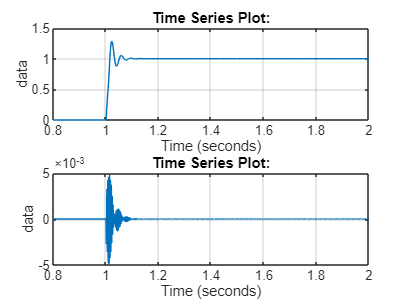

figure
subplot(2,1,1)
plot(gantry_out.pos_avg)
grid on
hold on
subplot(2,1,2)
plot(gantry_out.pos_diff)
grid on
hold on